# Bang Bang Control

Open serial to Pico data port

clear s % closes ports already open
s = serialport('COM4',9600) % Check COM#

s =   Serialport with properties:

                 Port: "COM4"
             BaudRate: 9600
    NumBytesAvailable: 0

  Show all properties, functions


Calculate linear fit parameters to find baseline voltages

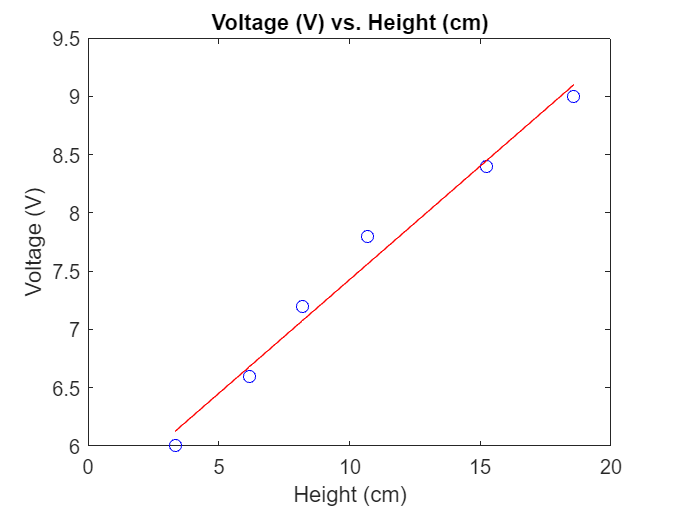

duty_cycle = [50 55 60 65 70 75]; % expiremented duty cycles
height = [3.352055 6.177309 8.201722 10.70005 15.25231 18.58077];
%hole_num = [3.5 5 6.5 7.5 9.5 11 12]; % resultant hole number

voltage = (duty_cycle ./ 100) .* 12; % convert duty_cycle to fan voltage
%height = hole_num .* 2; % convert hole_num to ball height

plot(height, voltage, 'bo') % plot data points

pfit = polyfit(height,voltage,1); % fit line to data 
pval = polyval(pfit, height); % evaluate fitted line

hold on
plot(height, pval, 'r') % plot fitted line
hold off

title("Voltage (V) vs. Height (cm)")
xlabel("Height (cm)")
ylabel("Voltage (V)")


% extract parameters
a = pfit(1)

a = 0.1950

b = pfit(2)

b = 5.4767

Send request for number of samples to Pico and begin live plotting

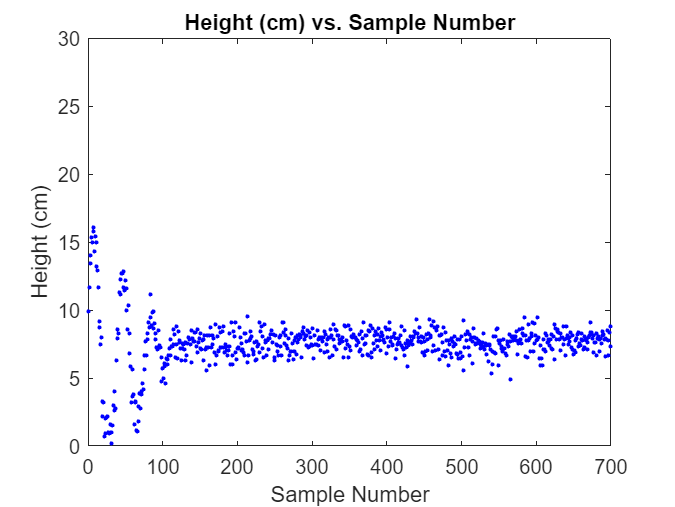

desired_height = 10; 
s.writeline(num2str(desired_height)) % send desired height to Pico

samples = 700;
s.writeline(num2str(samples)) % send number of samples to Pico

data = zeros(1, samples); % create emply row vector for data collection

% loop for every sample
for i = 1:samples   
    data(i) = s.readline(); % receive distance from serial
    plot(i,data(i),'b.') % plot data
    
    title("Height (cm) vs. Sample Number")
    xlabel("Sample Number")
    ylabel("Height (cm)") 
    axis([0 samples 0 30]) % x and y axis limits
    hold on
end
hold off

save data3_04_05_2024.mat data 

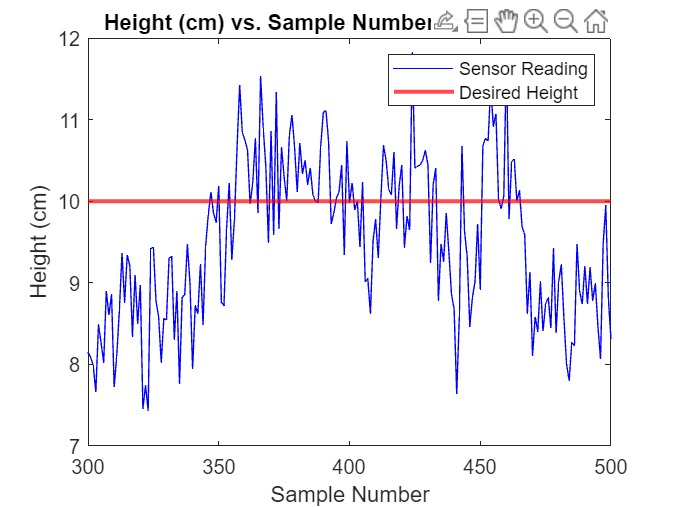

load data3_04_05_2024.mat

plot(data, "b") % plot data
hold on
yline(10, "r", "LineWidth", 2) % plot desired height 
hold off

%xlim([300 500])
xlim([0 500])
title("Height (cm) vs. Sample Number Trial 4 Zoomed")
xlabel("Sample Number")
ylabel("Height (cm)") 
legend("Sensor Reading", "Desired Height")